close all;
clear;
clc;


## Question 1

## part a-b


image = imread("data\Inputs\imgs\0004_6.png");
image_gray = im2double(rgb2gray(image));
n = 6;
[G, L] = pyrGen(image_gray, n);

i = 2

i = 3

i = 4

i = 5

i = 6

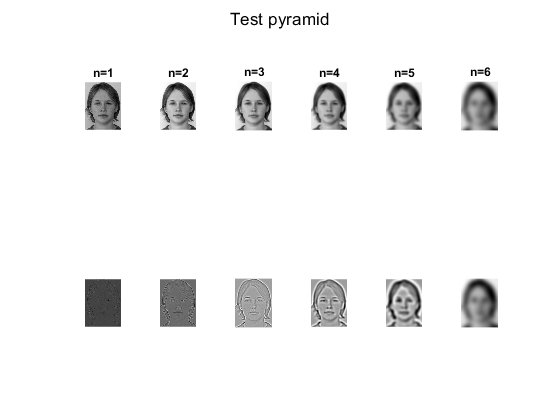


figure();
sgtitle('Test pyramid');
for i=1:n
    subplot(2,6,i);
    imshow(G{i}, []);
    title(['n=', num2str(i)]);
    
    subplot(2,6,6 + i);
    imshow(L{i}, []);
end

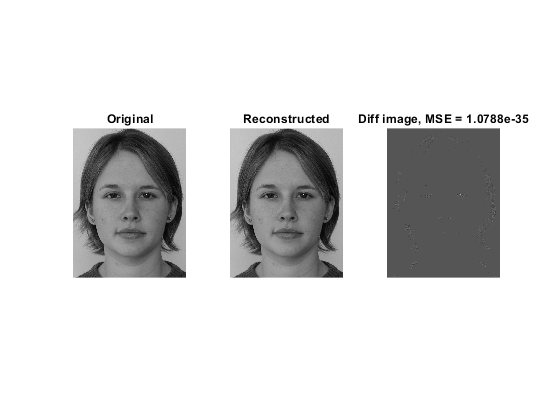


recon_image = imRecon(L);

sub_image = image_gray - recon_image;

mse = immse(image_gray, recon_image);

figure();
subplot(1,3,1);
imshow(image_gray, []);
title('Original');

subplot(1,3,2);
imshow(recon_image, []);
title('Reconstructed');

subplot(1,3,3);
imshow(sub_image, []);
title(['Diff image, MSE = ', num2str(mse)]);

## part c

I = im2double(imread("data\Inputs\imgs\0004_6.png"));
E = im2double(imread("data\Examples\imgs\6.png"));


















